clear all; close all;
[X1,fs] = audioread("Array_output_01.wav");
[X2,fs] = audioread("Array_output_02.wav");
[X3,fs] = audioread("Array_output_03.wav");
[X4,fs] = audioread("Array_output_04.wav");
X = [X1,X2,X3,X4];

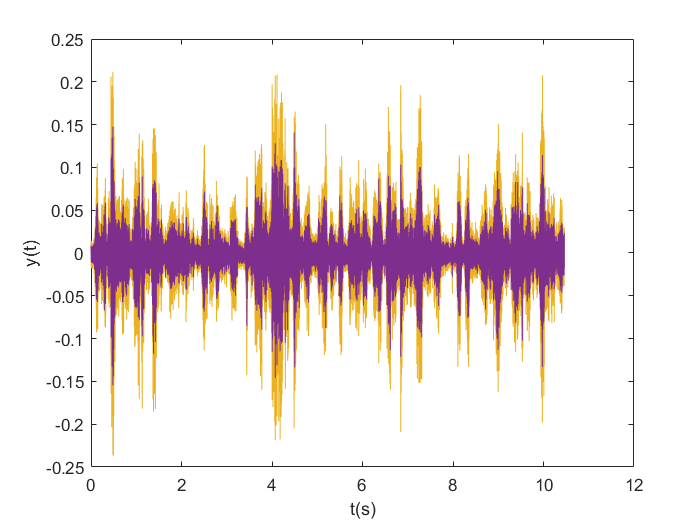

sound(X1)
N = length(X);
dt = 1 / fs;
t = 0:dt:(N*dt-dt);
y = X;
f = (-N/2:N/2-1)*fs/N;
Y = fftshift(fft(y))/N;
plot(t,y); xlabel('t(s)');ylabel('y(t)')

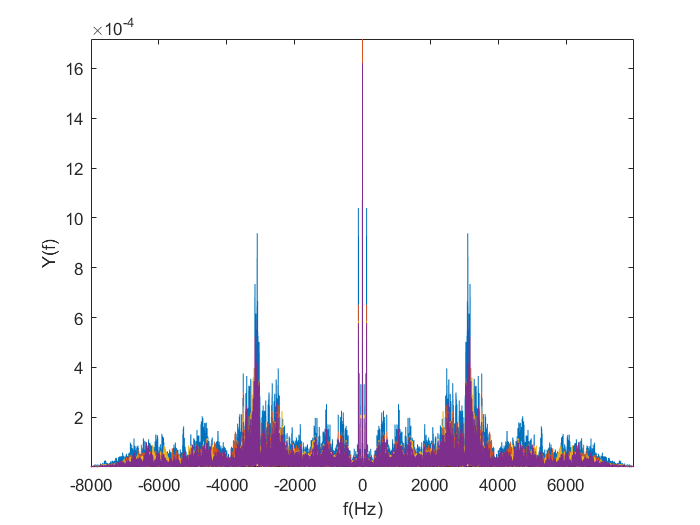

figure;
plot(f,abs(Y));axis([-inf inf -inf inf]);
xlabel('f(Hz)');ylabel('Y(f)')

[Frame,nSensors] = size(X);                            
J = nSensors;                                      
dx = 0.025;                                        
dy = 0;                                            
c = 340;                                             
n_source = 2;                                      
Index = linspace(0,J-1,J);
p = (-(J-1)/2 + Index.') * [dx dy]; 

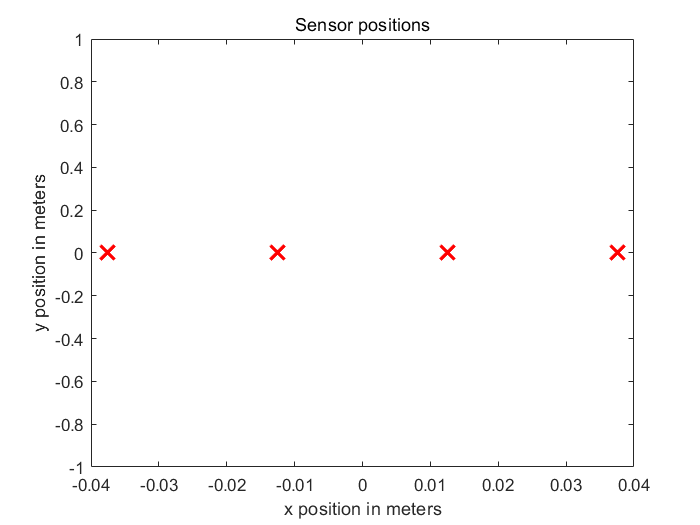

linspec = {'rx','MarkerSize',12,'LineWidth',2};
figure
plot(p(:,1),p(:,2),linspec{:});  
title('Sensor positions');
xlabel('x position in meters');
ylabel('y position in meters');

disp('The four microphones are ready !');

The four microphones are ready !


Leng = 684 ;                  %  Variable
Dim = round(Frame/Leng);
Half = round(Leng/2);
stride = 1;                                            
theta = -90:stride:90; 
voi = zeros(Leng,4,Dim);
for i = 1:Dim
    for h = 1:4
        voi(:,h,i) = fft(X(Half*(i-1)+1:Half*(i-1)+Leng,h)).*hann(Leng)/Leng;
    end
end
voi = voi(1:Half,:,:);

gd = permute(voi,[3,2,1]);
v = [sin(theta*pi/180);-cos(theta*pi/180)];
a_theta = zeros(4,181,Half);
fina = zeros(181,1);
for c = 1:Half
    R_x(:,:,c)=gd(:,:,c).'*(gd(:,:,c).')';
end
for i = 1:Half
    f_c = fs/(Leng)*(i-1);
    a_theta(:,:,i) = exp(-1j*2*pi*f_c*(p*v)./c);
    [eigvec,eigval] = eig(R_x(:,:,i));
    for j = 1:J 
        eigsc(1,j) = eigval(j,j);
        eigsc(2:J+1,j) = eigvec(:,j);
    end
    eigsc = (sortrows(eigsc',1))';
    Un(:,:,i) = [eigsc(2:J+1,1),eigsc(2:J+1,2)];
    o = diag(a_theta(:,:,i)'*(Un(:,:,i)*Un(:,:,i)')*a_theta(:,:,i));
    fina = fina + o;
end
P_sm = 1./fina; 

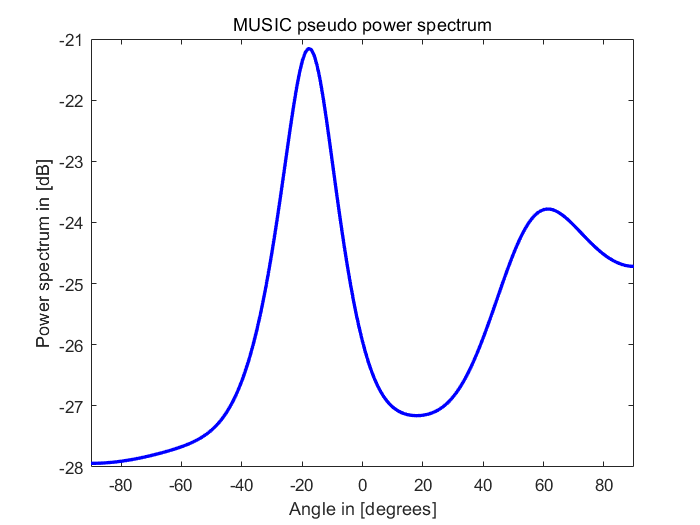

figure;
linspec = {'b-','LineWidth',2};
plot(theta, 10*log10(abs(P_sm)), linspec{:})
title('MUSIC pseudo power spectrum')
xlabel('Angle in [degrees]');
ylabel('Power spectrum in [dB]');
xlim([-90,90]);

P_middle = abs(P_sm(2:end-1));
P_front = abs(P_sm(1:end-2));
P_back = abs(P_sm(3:end)); 
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(P_sm(1));P_middle;abs(P_sm(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: -18 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 61 deg
